# Visualize Flow Data Using Quiver Plots

Quiver plots create arrows with varying directions and lengths that signify flow magnitude at specified Cartesian coordinates.

### Read Wind Data

We will use `wind.mat `to demonstrate how to create and customize quiver plots. This contains sample data that represents air currents over North America. Use a helper function to extract a subset of the data for visualization.

[X,Y,U,V] = readWindData();

### Basic Quiver Plot

Visualize a subset of the air current data to observe flow patterns.

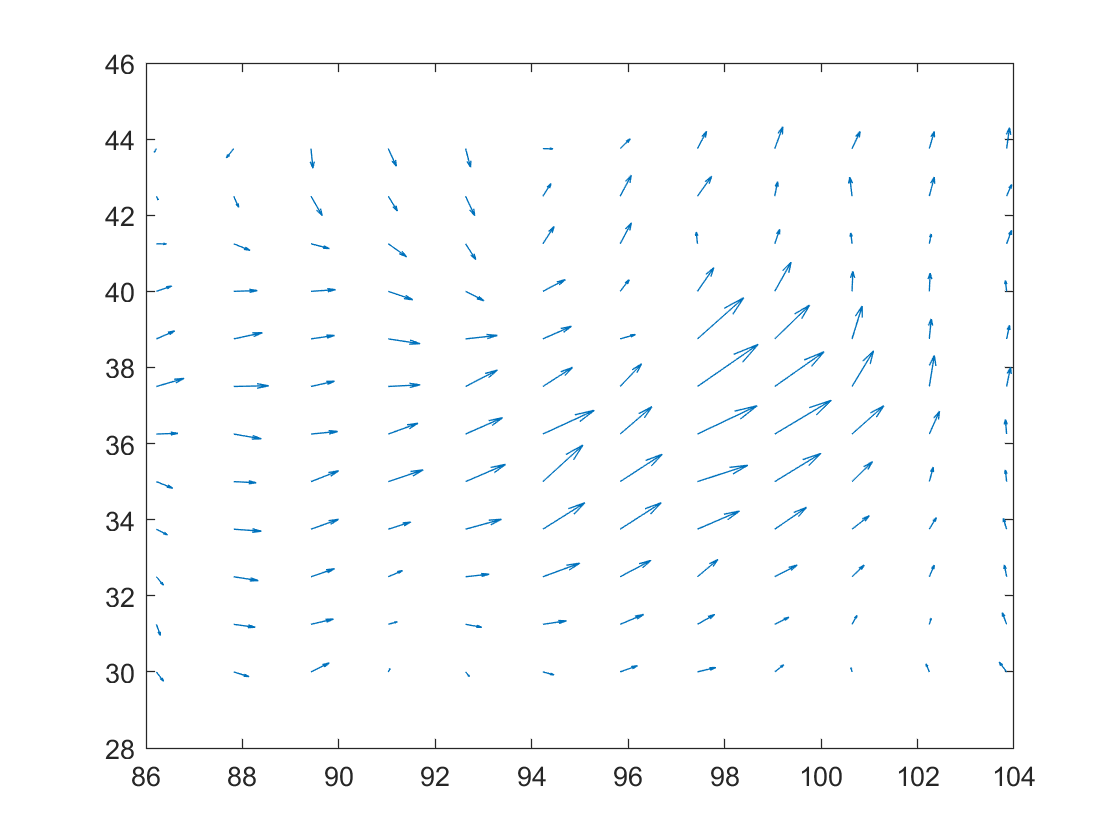

quiver(X,Y,U,V);

## Customization

### Modify Arrow Head and Marker

Use Name, Value pairs to modify the *ShowArrowHead* and *Marker *fields. Use *axis equal* to remove white space visible in the figure.

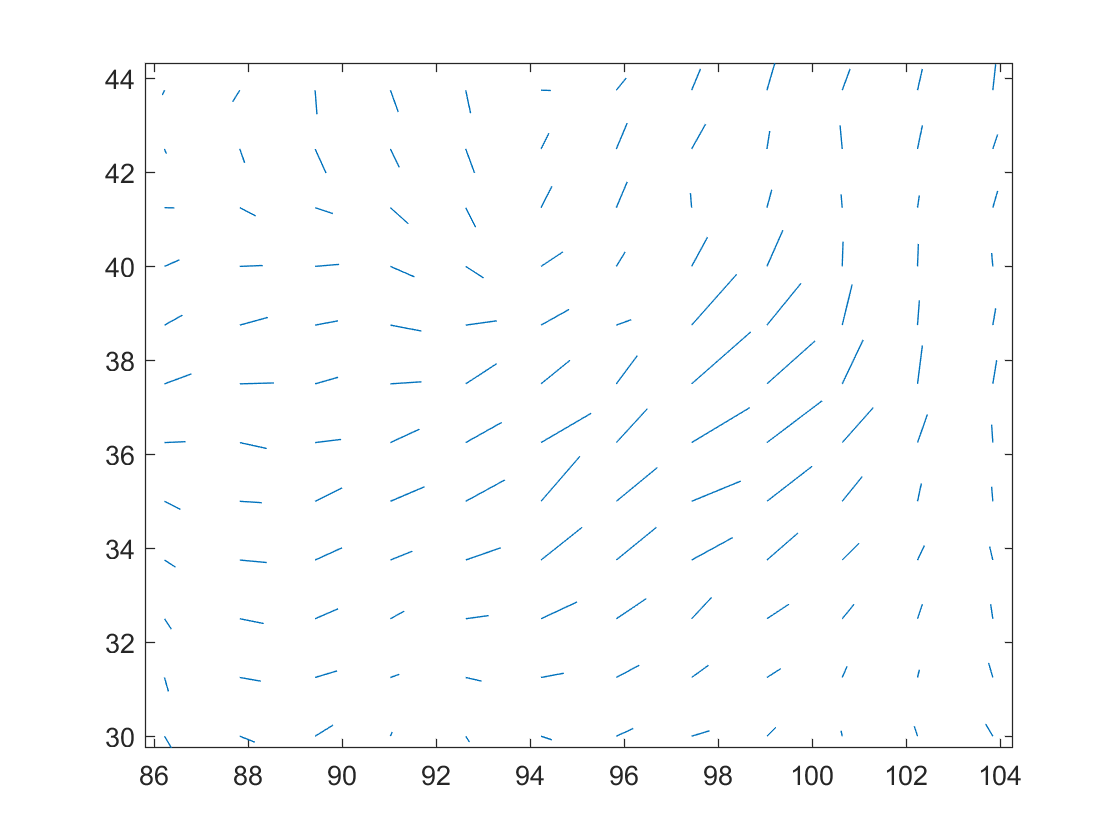

showArrowHead = "off";
MarkerType = 'none';

q = quiver(X,Y,U,V,...
    "ShowArrowHead",showArrowHead,...   % Specify if arrow heads show
    "Marker",MarkerType);               % Specify marker type
axis equal

### Specify Arrow Color

Use the 5th input to `quiver` to specify the arrow color.

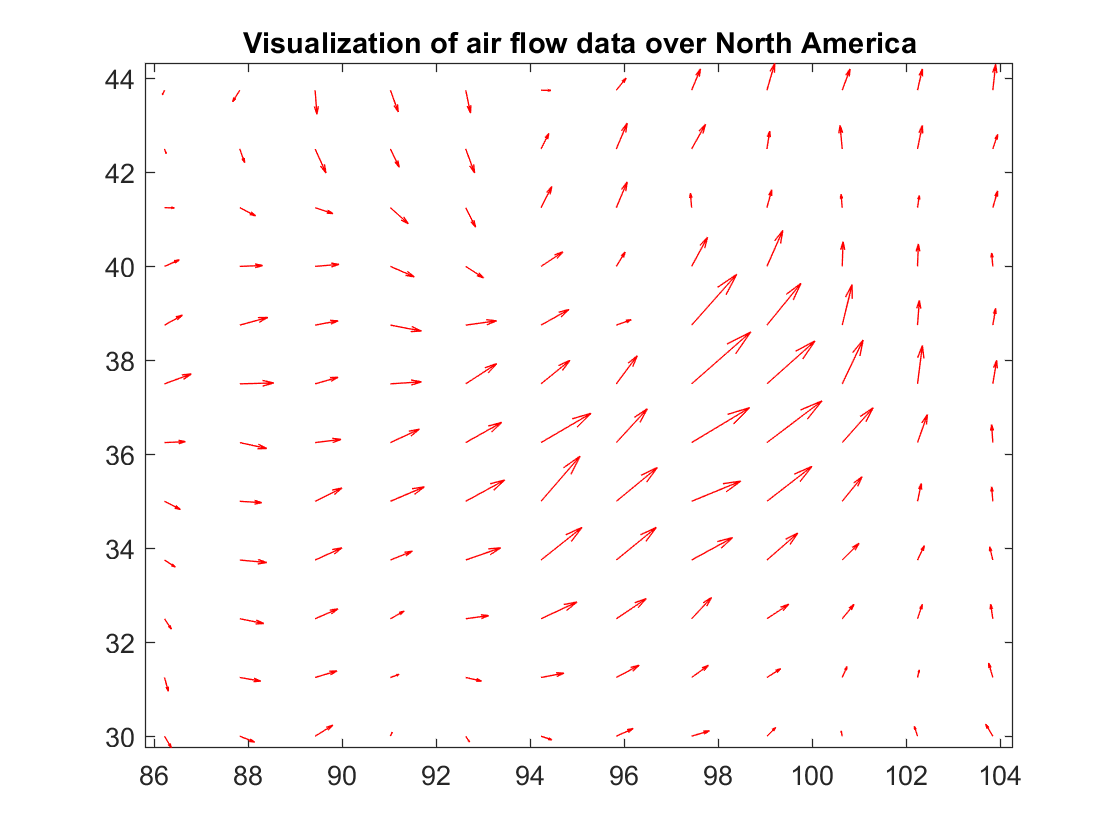

ArrowColor = 'r';

figure
q1 = quiver(X,Y,U,V,...
    ArrowColor);         % Specify arrow color
axis equal
title("Visualization of air flow data over North America")

## **Additional Information**

### **Get All Quiver Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Quiver, uncomment the following code. View or modify these properties using dot notation.

% get(q)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[quiver](https://www.mathworks.com/help/matlab/ref/quiver.html)

### Helper Function

This helper function reads in wind data, and extracts a subset of the data into variables X, Y, U and V.

function [X,Y,U,V] = readWindData()
    load wind
    X = x(11:22,11:22,1);
    Y = y(11:22,11:22,1);
    U = u(11:22,11:22,1);
    V = v(11:22,11:22,1);
end

Copyright (c) 2021, The MathWorks, Inc.